#### **Part 1**

- `ex6data1.mat` - Example Dataset 1

- `ex6data2.mat` - Example Dataset 2

- `ex6data3.mat` - Example Dataset 3

- `svmTrain.m` - SVM training function

- `svmPredict.m` - SVM prediction function

- `plotData.m` - Plot 2D data

- `visualizeBoundaryLinear.m` - Plot linear boundary

- `visualizeBoundary.m` - Plot non-linear boundary

- `linearKernel.m` - Linear kernel for SVM

- `submit.m` - Submission script that sends your solutions to our servers

- *`gaussianKernel.m` - Gaussian kernel for SVM

- *`dataset3Params.m` - Parameters to use for Dataset 3

#### **Part 2**

- `spamTrain.mat` - Spam training set

- `spamTest.mat` - Spam test set

- emailSample1.txt - Sample email 1

- emailSample2.txt - Sample email 2

- spamSample1.txt - Sample spam 1

- spamSample2.txt - Sample spam 2

- vocab.txt - Vocabulary list

- `getVocabList.m` - Load vocabulary list

- `porterStemmer.m` - Stemming function

- `readFile.m` - Reads a file into a character string

- `submit.m` - Submission script that sends your solutions to our servers

- *`processEmail.m` - Email preprocessing

- *`emailFeatures.m` - Feature extraction from emails

clear
dir

.                          ex6.mlx                    getVocabList.m             readFile.m                 token.mat                  
..                         ex6.pdf                    lib                        spamSample1.txt            visualizeBoundary.m        
dataset3Params.asv         ex6_companion.mlx          linearKernel.m             spamSample2.txt            visualizeBoundaryLinear.m  
dataset3Params.m           ex6data1.mat               matlab_main_file.mlx       spamTest.mat               vocab.txt                  
emailFeatures.asv          ex6data2.mat               plotData.m                 spamTrain.mat              
emailFeatures.m            ex6data3.mat               porterStemmer.m            submit.m                   
emailSample1.txt           gaussianKernel.asv         processEmail.asv           svmPredict.m               
emailSample2.txt           gaussianKernel.m           processEmail.m             svmTrain.m                 



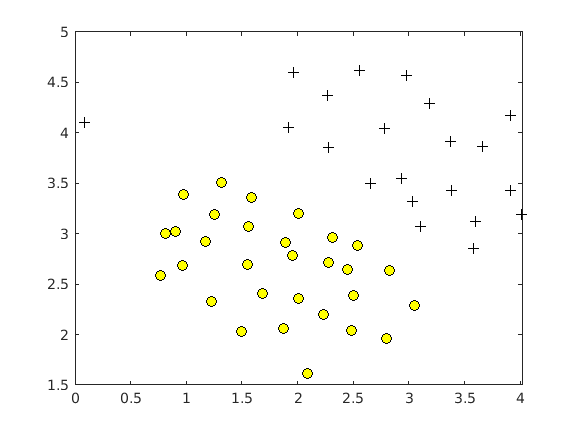

% Load from ex6data1: 
% You will have X, y in your environment
load('ex6data1.mat');

% Plot training data
plotData(X, y);

C = 1;
model = svmTrain(X, y, C, @linearKernel, 1e-3, 20);


Training ......................................................................
...............................................................................
............................................ Done! 



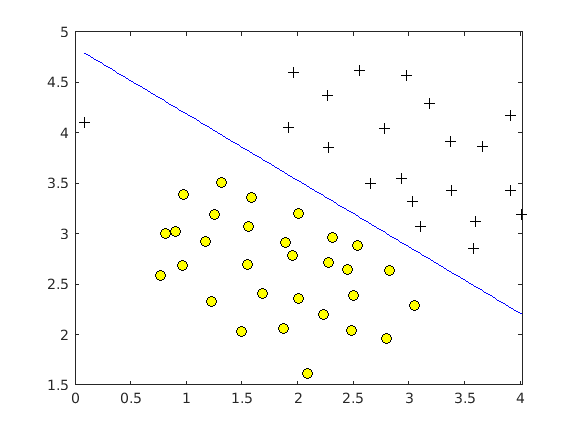

visualizeBoundaryLinear(X, y, model);

x1 = [1 2 1]; x2 = [0 4 -1]; 
sigma = 2;
sim = gaussianKernel(x1, x2, sigma);
fprintf('Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = %f : \n\t%g\n', sigma, sim);

Gaussian Kernel between x1 = [1; 2; 1], x2 = [0; 4; -1], sigma = 2.000000 : 
	0.324652


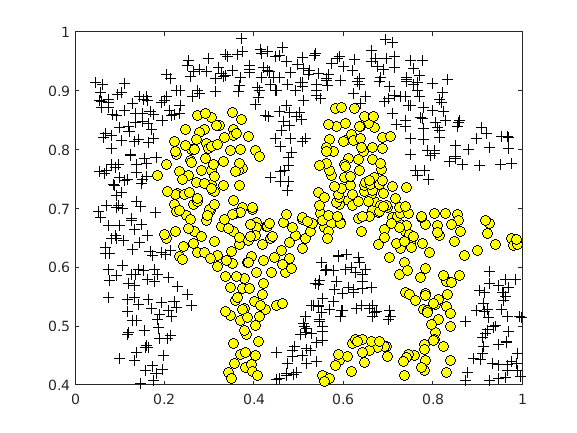

% Load from ex6data2: 
% You will have X, y in your environment
load('ex6data2.mat');

% Plot training data
plotData(X, y);   

% SVM Parameters
C = 1; sigma = 0.1;

% We set the tolerance and max_passes lower here so that the code will run faster. However, in practice, 
% you will want to run the training to convergence.
model= svmTrain(X, y, C, @(x1, x2) gaussianKernel(x1, x2, sigma)); 


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
...............................................................................
. Done! 



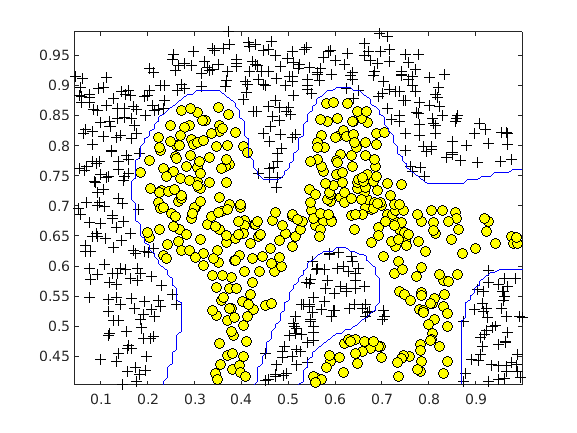

visualizeBoundary(X, y, model);

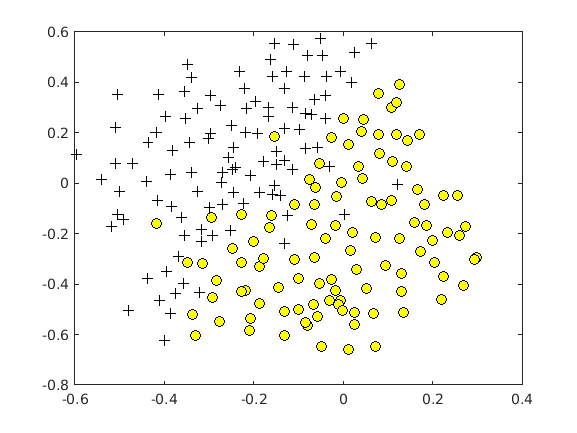

% Load from ex6data3: 
% You will have X, y in your environment
load('ex6data3.mat');

% Plot training data
plotData(X, y);

% Try different SVM Parameters here
[C, sigma] = dataset3Params(X, y, Xval, yval);

% Train the SVM
minError = 1.01;
optC = 0;
optSigma = 0;
for C = [0.01, 0.03, 0.1, 0.3, 1, 3, 10, 30]
    for sigma = [0.01, 0.03, 0.1, 0.3, 1, 3, 10, 30]
        model = svmTrain(X, y, C, @(x1, x2)gaussianKernel(x1, x2, sigma));
        predictions = svmPredict(model, Xval);
        error = mean(double(predictions ~= yval));
        if error < minError
            minError = error;
            optC = C;
            optSigma = sigma;
        end
    end
end


Training ......... Done! 


Training ............................................. Done! 


Training .................................................. Done! 


Training ............................... Done! 


Training ............................................ Done! 


Training ............................ Done! 


Training ................................... Done! 


Training ......................................... Done! 


Training ......... Done! 


Training ................................................................. Done! 


Training ................................................ Done! 


Training ......................................................................
...... Done! 


Training ....................................... Done! 


Training ....................................... Done! 


Training ............................... Done! 


Training ................................................. Done! 


Training ......... Done! 


Training ..................

C = optC;
sigma = optSigma;
model = svmTrain(X, y, C, @(x1, x2)gaussianKernel(x1, x2, sigma));


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
................................................................. Done! 



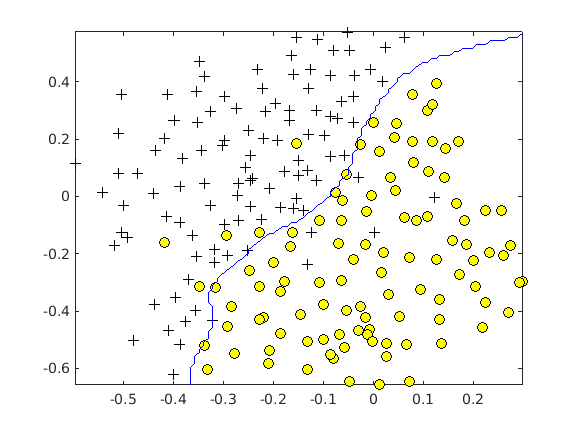


visualizeBoundary(X, y, model);

%% Initialization
clear;

% Extract Features
file_contents = readFile('emailSample1.txt');
word_indices  = processEmail(file_contents);


==== Processed Email ====

anyon know how much it cost to host a web portal well it depend on how mani 
visitor you re expect thi can be anywher from less than number buck a month 
to a coupl of dollarnumb you should checkout httpaddr or perhap amazon ecnumb 
if your run someth big to unsubscrib yourself from thi mail list send an 
email to emailaddr 



% Print Stats
disp(word_indices)

  Columns 1 through 12

          86         916         794        1077         883         370        1699         790        1822        1831         883         431

  Columns 13 through 24

        1171         794        1002        1893        1364         592        1676         238         162          89         688         945

  Columns 25 through 36

        1663        1120        1062        1699         375        1162         479        1893        1510         799        1182        1237

  Columns 37 through 48

         810        1895        1440        1547         181        1699        1758        1896         688        1676         992         961

  Columns 49 through 53

        1477          71         530        1699         531



% Extract Features
features = emailFeatures(word_indices);

% Print Stats
fprintf('Length of feature vector: %d\n', length(features));

Length of feature vector: 1899


fprintf('Number of non-zero entries: %d\n', sum(features > 0));

Number of non-zero entries: 45


% Load the Spam Email dataset
% You will have X, y in your environment
load('spamTrain.mat');
C = 0.1;
model = svmTrain(X, y, C, @linearKernel);


Training ......................................................................
...............................................................................
...............................................................................
...............................................................................
.. Done! 




p = svmPredict(model, X);
fprintf('Training Accuracy: %f\n', mean(double(p == y)) * 100);

Training Accuracy: 99.850000



% Load the test dataset
% You will have Xtest, ytest in your environment
load('spamTest.mat');

p = svmPredict(model, Xtest);
fprintf('Test Accuracy: %f\n', mean(double(p == ytest)) * 100);

Test Accuracy: 98.800000


% Sort the weights and obtin the vocabulary list
[weight, idx] = sort(model.w, 'descend');
vocabList = getVocabList();
for i = 1:15
    if i == 1
        fprintf('Top predictors of spam: \n');
    end
    fprintf('%-15s (%f) \n', vocabList{idx(i)}, weight(i));
end

Top predictors of spam: 


our             (0.503125) 
click           (0.464724) 
remov           (0.419005) 
guarante        (0.385966) 
visit           (0.369754) 
basenumb        (0.344550) 
dollar          (0.326996) 
will            (0.274346) 
price           (0.269919) 
pleas           (0.262902) 
most            (0.258072) 
nbsp            (0.255980) 
lo              (0.253748) 
hour            (0.240515) 
da              (0.238591) 
